# Confidence regions

t = [3.4935 4.2853 5.1374 5.8181 6.8632 8.1841]';

x = [6 10.1333 14.2667 18.4000 22.5333 26.6667]';

sig = 0.1;

m = length(t);

## No.1

### Simplify the expression for the covariance matrix C

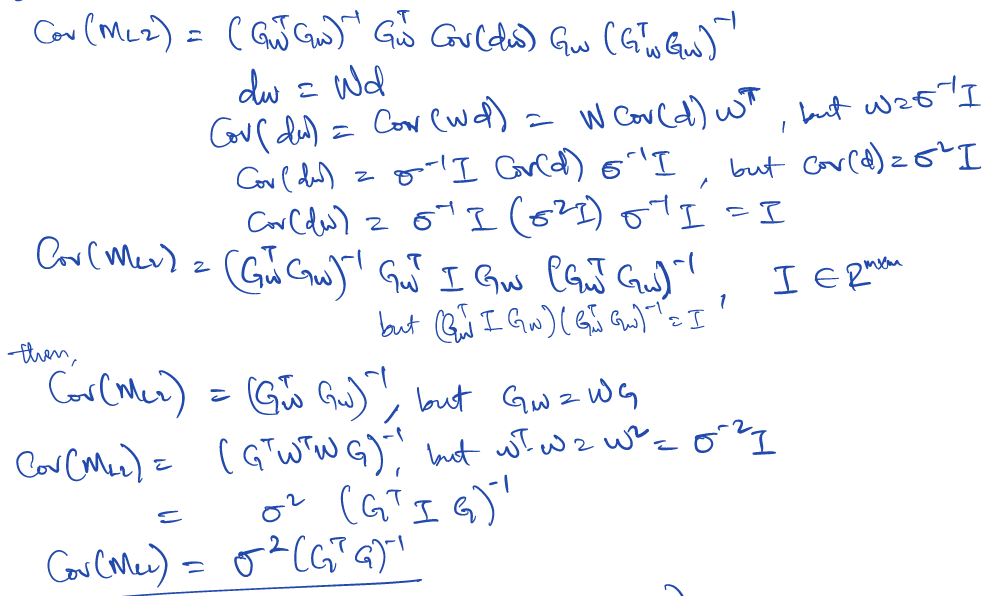

### Compute C and discuss the meaning of the elements of the matrix.

G = [ones(m,1) x]; % matrix G

C = (sig^2)*inv(G'*G)

C =     0.0106   -0.0005
   -0.0005    0.0000


### Discuss the meaning of the elements of the matrix.

The element C(1,1) is the variance of the first parameter estimate found by least squares , C(1,2) and C(2,1) are the products of the standard deviations of the first and second  parameter estimates found by least squares, C(2,2) is the variance of the second parameter estimate found by least squares.

## No.2

### Compute the individual 95% confidence interval for each parameter.

M_L2 = inv(G'*G)*G'*t; % lest square solution

za = 1.96; % 95% confidence interval
n = 2;

% first parameter
s1 = sqrt(C(1,1)); % standard deviation

% confidence intervals with n
c1 = M_L2(1) - za*s1/sqrt(n);
c2 = M_L2(1) + za*s1/sqrt(n);

cofidence_interval_first_n = [c1 c2]

cofidence_interval_first_n =     1.8897    2.1750


% confidence intervals without n
c1 = M_L2(1) - za*s1;
c2 = M_L2(1) + za*s1;

cofidence_interval_first = [c1 c2]

cofidence_interval_first =     1.8306    2.2340


% Second parameter
s2 = sqrt(C(2,2)); % standard deviation

% confidence intervals with n
c11 = M_L2(2) - za*s2/sqrt(n);
c22 = M_L2(2) + za*s2/sqrt(n);

cofidence_interval_second_n = [c11 c22]

cofidence_interval_second_n =     0.2123    0.2283


% confidence intervals without n
c11 = M_L2(2) - za*s2;
c22 = M_L2(2) + za*s2;

cofidence_interval_second = [c11 c22]

cofidence_interval_second =     0.2089    0.2316


### Comment on including and excluding n

In both cases using n to calculate the confidence interval gives us a small region, compared to when n is included, as we obtain a larger region for the confidence interval.

### Discuss why this may not be a good estimate of the parameter uncertainty.

Because $(\sigma_{ls})_{1} (\sigma_{ls})_{2} \ne 0$, then the computed confidence interval doesn't capture the relationship between $m_{1}$ and $m_{2}$

## No.3

### Calculate  the model parameter correlation matrix.

rho1 = C(1,1)/sqrt(C(1,1)*C(1,1));
rho12 = C(1,2)/sqrt(C(1,1)*C(2,2));
rho = [rho1 rho12;rho12 rho1]

rho =     1.0000   -0.9179
   -0.9179    1.0000


### Comment on the model parameter correlation matrix.

The two model parameters are highly negatively statically dependent and correlated, meaning the projection os needle-like with its long principle axis having a negative slope.

## No.4

### Define the inequality for the ellipsoid that defines the confidence region and explain its meaning. 

The inequality , $$$\frac{(m_{1} - (m_{ls})_{1})^{2}}{(\sigma_{m})_{1}^{2}} + \frac{(m_{2} - (m_{ls})_{2})^{2}}{(\sigma_{m})_{2}^{2}}  < \Delta^{2}$$$,  where $\Delta^{2}$ represents the $95\%$ confidence region for the $\chi_{2}^{2}$ random variable with two degrees of freedom, $m_{ls}$ is the least square estimate. This inequality enables us to model $m_{1}$ and $m_{2}$ using an ellipsoid with major and minor radii of $(\sigma_{m})_{1}$ and $(\sigma_{m})_{2}$ respectively dependingon how axes $m_{1}$ and $m_{2}$ are defined. The parameter estimates lie within the region enclosed by the ellipsoid. i.e. $\frac{(m_{1} - 2.0323)^{2}}{0.0106} + \frac{(m_{2} - 0.2203)^{2}}{0.000034}  < 5.9915$ 

### No.5

### Diagonalize $$C^{-1}$$

% eigenvalues 
[Q,lam] = eig(inv(C));
Cinv = Q*lam*Q'

Cinv = 	1.0e+05 *

    0.0060    0.0980
    0.0980    1.8996


### Discuss the benefits of using this decomposition to define a confidence region for the parameter estimates.

- The intervals obatined are significantly larger than that obtained while using individual estimates since this is based on projecting joint parameter confidence regions onto coordinate axes $m_{i}$.

- Also because the covariance matrix and its inverse are symmetric and positive definites, therefore $C^{-1}$ is diagonalizable. This enables us to know the direction and  of the the principal axes of the ellipsoid  and its length using the eigen vectors eigen values obtained from C respectively.

## No.6

### Plot the error ellipsoid in the (t0, s2) plane.

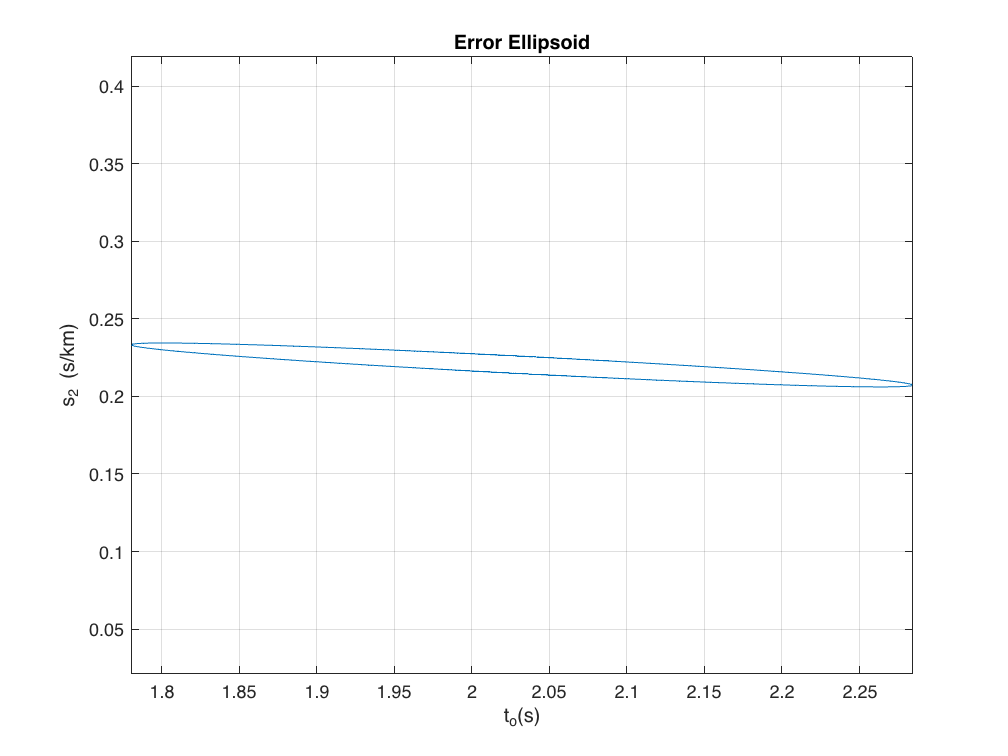

Delta = chi2inv(0.95,2); %Delta2

figure(1)
plot_ellipse(Delta,C,M_L2) ; grid on
title('Error Ellipsoid')
% xlim([1.77,2.29])
xlabel('t_o(s)'); ylabel('s_2 (s/km)')

### Compare the ellipsoids as uncertainty estimates to the confidence intervals as uncertainty estimates.

The uncertainty estimates obtained from the ellipsoids lie in a very small confidence region whose width narrows as it tends to the vertices and with a longer length ($$\approx 2.28-1.78$ $) while the confidence intervals uncertainity estimates lie in the box of constant width ($0.2283 - 0.2123$) and shorter length ($$2.1750 - 1.8897$$) this implies a bigger region for the uncertaininty estimates. This means that the confidence interval has a wider region in width compared to the confidence region (ellipsoid) with a longer length, however the ellipsoid give more accurate parameter estimates near to the center.

function plot_ellipse(DELTA2,C,m)
n=5000;

%construct a vector of n equally-spaced angles from (0,2*pi)
theta=linspace(0,2*pi,n)';

%corresponding unit vector
xhat=[cos(theta),sin(theta)];
Cinv=inv(C);

%preallocate output array
r=zeros(n,2);
for i=1:n
%store each (x,y) pair on the confidence ellipse in the corresponding row of r
r(i,:)=sqrt(DELTA2/(xhat(i,:)*Cinv*xhat(i,:)'))*xhat(i,:);
end

% Plot the ellipse and set the axes.
plot(m(1)+r(:,1), m(2)+r(:,2));
axis equal
end